# Thermoeconomic Analysis Demo

Use `ThermoeconomicAnalysis` function to compute the exergy cost of a plant

#### Select and read the data model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(1));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.SampleNames);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Make Cost Analysis

Compute cost and show the results

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);


Process Exergy Cost - T1180

Key         P*(MW)    Pin*(MW)    Pex*(MW)      F*(MW)      R*(MW)
———————————————————————————————————————————————————————————————————
COMB       171.845     163.772       8.072     169.000       2.845
CMP         55.956      52.908       3.048      55.611       0.344
TRB        107.693     102.458       5.235     107.508       0.185
APH         39.717      37.537       2.180      39.388       0.330
HRSG        21.245      20.247       0.998      21.245       0.000
STCK         3.704       3.530       0.174       3.704       0.000


Process Unit Exergy Cost - T1180

Key        kP*(J/J)    kin*(J/J)    kex*(J/J)     kF*(J/J)     kR*(J/J)       k(J/J)
—————————————————————————————————————————————————————————————————————————————————————
COMB         1.6609       1.5829       0.0780       1.3605       0.0275       1.2007
CMP          1.8964       1.7931       0.1033       1.7361       0.0117       1.0856
TRB          1.7361       1.6517       0.0844       1.66

#### Show the default thermoeconomic analysis graph

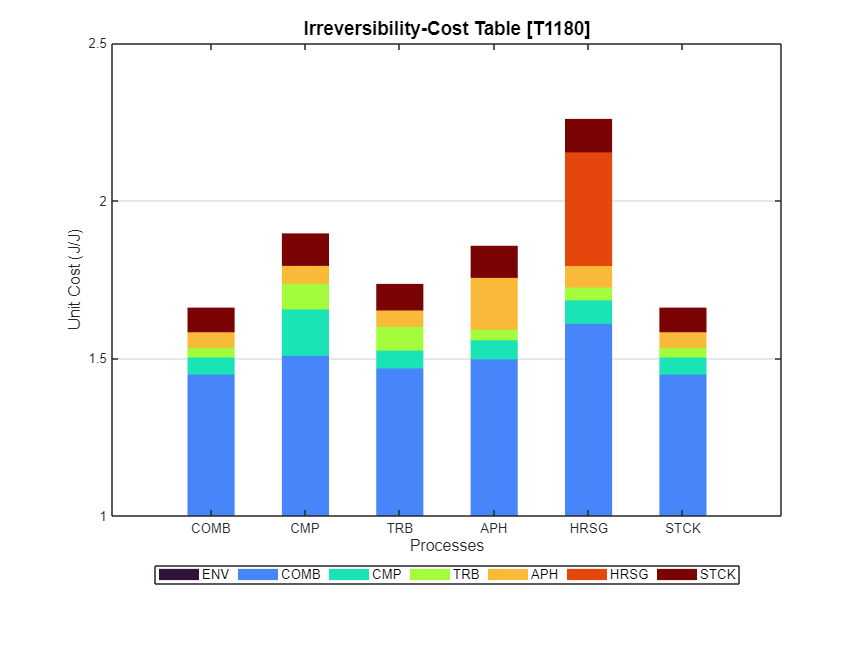

ShowGraph(res);

#### Additional Help

help ThermoeconomicAnalysis

 ThermoeconomicAnalysis gets the termoeconomic analysis of a plant state.
    Calculate the exergy cost, Fuel-Product and Irreversibility-Cost tables.
    If the data model has information on resource costs, generalised costs can be calculated, 
    otherwise only direct costs can be calculated.
    With the option 'CostTables' we choose the type of costs we want to calculate. 
    With the option 'ResourceSample' we choose the resource cost sample data.
 
    Syntax
      res=ThermoeconomicAnalysis(data,Name,Value)
 
    Input Arguments
  	  data - cDataModel object which contains the data model
 
    Name-Value Arguments
      State - Thermoeconomic state id. If missing first sample is taken
        array char | string
      CostTables - Indicate which cost tables are calculated
        'DIRECT' calculates direct exergy cost tables
        'GENERALIZED' calculates generalized exergy cost tables
        'ALL' calculate both kind of tables
      Resour